# Extracting Timetables... Simulink style

[ ](https://matlab.mathworks.com/open/github/v1?repo=simulink/blog&project=2025_08_29_extractTimeTable/ExtractTimetable.prj)

Today I want to share a simple tip to interact with data logged from a Simulink model

## The Problem

Let's take this simple model that logs 3 signals with different sample times:

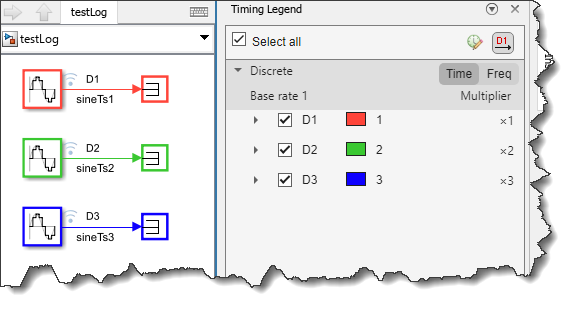

After simulating, it is possible to use [`extractTimetable`](https://www.mathworks.com/help/simulink/slref/simulink.simulationdata.dataset.extracttimetable.html) to create a single [`timetable`](https://www.mathworks.com/help/releases/R2025a/matlab/ref/timetable.html) with all the logged signals:

out = sim('testLog');
TT = out.logsout.extractTimetable

TT = 11×3 timetable
     Time     sineTs1     sineTs2    sineTs3
    ______    ________    _______    _______

    0 sec            0          0          0
    1 sec     0.062791        NaN        NaN
    2 sec      0.12533    0.12533        NaN
    3 sec      0.18738        NaN    0.18738
    4 sec      0.24869    0.24869        NaN
    5 sec      0.30902        NaN        NaN
    6 sec      0.36812    0.36812    0.36812
    7 sec      0.42578        NaN        NaN
    8 sec      0.48175    0.48175        NaN
    9 sec      0.53583        NaN    0.53583
    10 sec     0.58779    0.58779        NaN


What's the problem? In one word: **NaN**.

By default, `extractTimetable` inserts [`NaN`](https://www.mathworks.com/help/matlab/ref/nan.html) for steps where signals with a sample time slower than the fastest rate did not execute. While this is technically correct because there was no data point at this time, I find this not ideal for data logged from Simulink. 

In Simulink, if I was to connect a [Rate Transition](https://www.mathworks.com/help/simulink/slref/ratetransition.html) block and other blocks downstream from this logged signal, they would not receive NaNs. Instead, the previous value would be held.

Those NaNs also make plots look strange. Here is the data as seen in the [Simulation Data Inspector](https://www.mathworks.com/help/releases/R2025a/simulink/slref/simulationdatainspector.html):

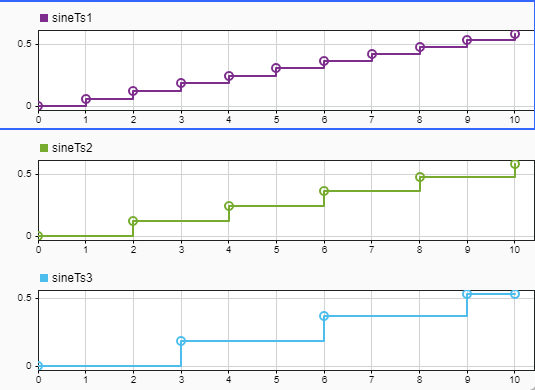

When plotting the timetable, the NaNs cause gaps in the signals:

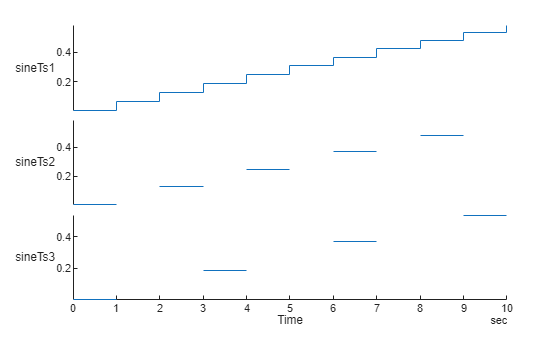

stackedplot(TT)

## The Solution

To obtain a timetable that I find better aligned with Simulink's behavior, you can first extract the data as a cell array that contains one timetable per sample time, and then combine them using the synchronize function:

TT = out.logsout.extractTimetable(OutputFormat="cell-by-sampletime");
TT = synchronize(TT{:},"union","previous")

TT = 11×3 timetable
     Time     sineTs1     sineTs2    sineTs3
    ______    ________    _______    _______

    0 sec            0          0          0
    1 sec     0.062791          0          0
    2 sec      0.12533    0.12533          0
    3 sec      0.18738    0.12533    0.18738
    4 sec      0.24869    0.24869    0.18738
    5 sec      0.30902    0.24869    0.18738
    6 sec      0.36812    0.36812    0.36812
    7 sec      0.42578    0.36812    0.36812
    8 sec      0.48175    0.48175    0.36812
    9 sec      0.53583    0.48175    0.53583
    10 sec     0.58779    0.58779    0.53583


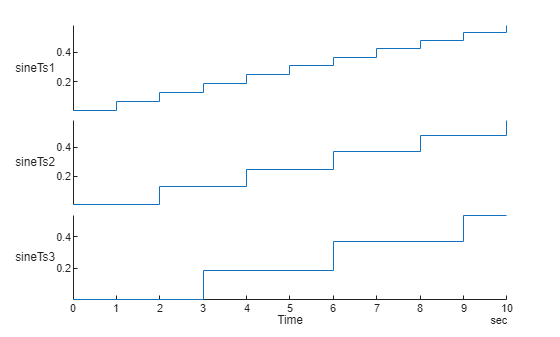

stackedplot(TT)

## Now it's your turn

Do you prefer the default behavior of `extractTimetable`? Would you prefer if the "zero-order hold" behavior shown in this post was the default? Let us know in the comments below.